# Offset-Free Control using Observer based LQOC  

**Sachin C. Patwardhan*, Anjali P. Deshpande and Sharad Bhartiya* **

(*) Dept. of Chemical Engineering,

 Indian Institute of Technology Bombay, Mumbai 400076 India  

## Introduction

In the previous lesson, we have seen implementation of state feedback controller using state estimators. We have seen that the controller is unable to regulate the states in the presence of plant model mismatch and disturbances.  If it is desired to achieve offset free control in the face of unmeasured disturbances or MPM or move the system from the equilibrium point to an arbitrary setpoint, then the state feedback control law has to be further modified. In this lesson, we will see how the control law is modified. The efficacy of the developed controller is further demonstrated with Q Tank example.

**Learning objectives** are: 

- Modify state feedback regulator by introducing moving target states and target inputs for dealing with unmeasured disturbances and model plant mismatch 

- Understand effect of innovation filter tuning on manipulated input behavior in presence of noise 

## Setpoint Tracking and Disturbance Rejection 

 In the previous lesson, we have observed that the state feedback regulator generates an offset if the unmeasured disturbances influencing state dynamics are non-stationary and no provision is made to compensate for their effects.  In order to deal with such situations**, **it is necessary to introduce integral action in the controller. As discussed in [Module 4](matlab:open('../4. Model_Preictive_Control_Vanilla_Versions/L2_Target_Tracking_MPC.mlx')), one method to achieve this is to modify the state state feedback control law using time varying target states and target inputs. In Module 4, we have computed target state state and target inputs using ***open loop observer, ***i.e. $L$ equals null matrix. We need to modify the target state computations now to account for the fact that a state estimator given by 

$\hat{x\;} \left(k+1\right)=\Phi \widehat{x} \left(k\right)+\Gamma u\left(k\right)+Le\left(k\right)$---------(1)

$e\left(k\right)=y\left(k\right)-C\hat{x\;} \left(k\right)$--------(2)

is used as an internal model. The innovation signal, $e\left(k\right)=y\left(k\right)-C\hat{x\;} \left(k\right)$, contains information about unmeasured disturbances and MPM. 

Under the assumption that $e\left(k+j\right)=e\left(k\right)\;\textrm{for}\;j>k$, moving equilibrium point of the internal model can be found by solving for

${\widehat{x} }_s \left(k\right)=\Phi {\widehat{x} }_s \left(k\right)+\Gamma u_s \left(k\right)+L\;e\left(k\right)$   ------(3)

$y_s \left(k\right)=C{\widehat{x} }_s \left(k\right)+e\left(k\right)$   ------(4)

Eliminating ${\widehat{x} }_s \left(k\right)$ in equation (4) using

 $x_s \left(k\right)={\left(I-\Phi \right)}^{-1} \left(\Gamma u_s \left(k\right)+\textrm{Le}\left(k\right)\right)$  ----(5)

we arrive at 

$\begin{array}{l}
y_s \left(k\right)=\left(C{\left(I-\Phi \right)}^{-1} \Gamma \right)\;u_s \left(k\right)+\left(I+C{\left(I-\Phi \right)}^{-1} L\right)\;e\left(k\right)\\
\;\;\;\;\;\;\;\;\;\;=\;G\;u_s \left(k\right)+G_e \;e\left(k\right)
\end{array}$ ------(6)

Setting $y_s \left(k\right)=r\left(k\right)$, when $l=m$, we can derive expression for $u_s \left(k\right)$ as follows 

 $u_s \left(k\right)={\left(G\right)}^{-1} \;\left(r\left(k\right)-G_e \;e\left(k\right)\right)$------(7)

When $u_s \left(k\right)$ computed using (7) is outside the input bounds, or when $l\not= m$, the target state can be computed by solving $u_s \left(k\right)$ can be found by solving the following optimization problem

$\min_{u_s \left(k\right)} \left\lbrace {\left(r\left(k\right)-y_s \left(k\right)\right)}^T \;W_{\textrm{ys}} \left(r\left(k\right)-y_s \left(k\right)\right)\right\rbrace$   ------(8)

subject to,

$y_s \left(k\right)=G\;u_s \left(k\right)+G_e \;e\left(k\right)$ ------(9) 

$u^L \le u_s \left(k\right)\le u^H$ ------ (10)

In either case, $x_s \left(k\right)$ can be found using equation (25). Using target states and target inputs, the control law is modified as follows 

$\begin{array}{l}
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\Delta u\left(k\right)=-G\Delta x\left(k\right)\\
\Delta x\left(k\right)=x\left(k\right)-x_s \left(k\right)\;\;\textrm{and}\;\;\Delta u\left(k\right)=u\left(k\right)-u_s \;\left(k\right)
\end{array}$   -------(11)

 Thus, the state feedback control law that solves **servo and regulatory problems simultaneously **can be expressed as follows:

$u\left(k\right)=u_s \left(k\right)-G\left\lbrack x\left(k\right)-x_s \left(k\right)\right\rbrack$   ------(12)

We now implement the control law as given in equation (12) for the Q Tank process. A time varying disturbance input signal is given to the process. 

### **Closed Loop simulations using Q-Tank System **

 
clear all
clc
global QTank U_k D_k  % Define global variables for quadruple tank 

Set_Graphics_Parameters ;

**Task 1**: Select the operating point for Q Tank process.  Set it as Non-minimum phase

operating_pt=2;

% Load quadruple tank parameters and steady state 
% The following file loads QTank data structure 
if operating_pt==1
load QTank_MinPhase_Model
else
 load QTank_NonMinPhase_Model 
end

phy= QTank.phy ;  
gam = QTank.gama_u ;
gam_d = QTank.gama_d ; 
C_mat = [1 0 0 0 ; 0 1 0 0]  ; % Levels h(1) and h(2) are measured in quadruple tank 
[n_op, nx ] = size(C_mat)  ;
[n_st, n_ip] = size(gam) ;
[nx, n_d] = size(gam_d) ;

u_H = [5 5]' - QTank.Us ;  % Physical Input bounds low are 0 and 5 Volts 
u_L = [0 0]' - QTank.Us ;  % Steady state inputs are [3 3] 

QT_sys = ss(phy, [gam gam_d], C_mat, zeros(n_op,n_ip+n_d), QTank.samp_T ) ;
Q_mat = 0.0025 ;
R_mat = QTank.R_mat ;


**Task 2:**  LQOC tuning matrices and controller design, LQOC tuning matrices are given as

 $W_y =\left\lbrack \begin{array}{cc}
\alpha_1  & 0\\
0 & \alpha_2 
\end{array}\right\rbrack$,  $W_u =\left\lbrack \begin{array}{cc}
\beta_1  & 0\\
0 & \beta_2 
\end{array}\right\rbrack$, $W_{x}=[C^{T}W_{y}C]   ;   W_{N}=[C^{T}W_{yN}C]$

% LQOC tuning matrices and controller design 
beta(1)=0.095;
beta(2)=0.01;
disp('Input weighting matrix')

Input weighting matrix


Wu = diag(beta);
alpha(1)=10;
alpha(2)=10;
disp('Output weighting matrix')

Output weighting matrix


Wy = diag(alpha);  % Output weighting matrix
Wx_y = C_mat' * Wy * C_mat ;

We then compute the controller gain using [dlqr](https://in.mathworks.com/help/control/ref/lti.dlqr.html) command in MATLAB

[G_inf,S_inf, Eig_CL_con] = dlqr(phy, gam, Wy, Wu, zeros(n_st,n_ip)) ;

[G_inf,S_inf, Eig_CL_con] = dlqr(phy, gam, Wx_y, Wu, zeros(n_st,n_ip)) ;
disp('Controller gain is')

Controller gain is


G_inf

G_inf =     2.4305    2.0119   -0.7531    1.5194
    2.7315    2.3756    2.0211   -2.1554


disp('Maximum Absolute Closed loop Eigen value')

Maximum Absolute Closed loop Eigen value


rho_con = max(abs(Eig_CL_con)) 

rho_con = 0.9540

** Task 3: Kalman predictor design **

Kalman predictor is designed using MATLAB command [kalman](https://in.mathworks.com/help/control/ref/ss.kalman.html?websocket=on#mw_3ba98894-fd69-40c7-812d-569904ed6fd4)

 [KEST,L_inf,P_inf] = kalman(QT_sys, Q_mat, R_mat, zeros(n_d,n_op),'delayed')  ;
 disp('Kalman Predictor Gain is')

Kalman Predictor Gain is


 L_inf

L_inf =     0.0107    0.0140
    0.0144    0.0208
    0.0075    0.0082
    0.0146    0.0169


 disp('Maximum Absolute Eigen value of phy-LC')

Maximum Absolute Eigen value of phy-LC


 rho_obs = max(abs(eig(phy - L_inf * C_mat )))

rho_obs = 0.9423


N = 601 ; 
xk = zeros(n_st,N);
xs_k = zeros(n_st,N);
yk = zeros(n_op,N) ;
est_err = zeros(n_st,N); 
xkhat = zeros(n_st,N);
xk(:,1) =0.5*[1 -1 1 -1]';
uk = zeros(n_ip,N) ;
us_k = zeros(n_ip,N) ;
dk = zeros(1,N) ;
ek = zeros(n_op,N) ;

The gains $G\;\textrm{and}\;G_e \;$are then computed using equation (26), which are then used in the computation of target states and target inputs.

Gain_ss = C_mat * inv(eye(n_st)-phy)*gam ; 
Gain_e = eye(n_op) + C_mat * inv(eye(n_st)-phy)* L_inf ;
rk = zeros(n_op,1) ;
r_k = zeros(n_op, N) ;  % Array to save time varying setpoints

Further we add disturbance input to the process. A time varying disturbance input signal is generated using **idinput** command in MATLAB

  dk_prbs = 0.2 * idinput(401, 'rgs', [0.0 0.025] ) ; 
  dk(201:N) = 0.4 + dk_prbs ; 

**Task 5:** Select Plant_Sim as Nonlinear for simulating Q Tank process using a nonlinear ODE model.

Plant_Sim =0  ; 

for k = 1:N-1
   

    kT(k) = (k-1);
    if (k >= 400),   rk = [ 3 -3 ]';  end

    r_k(:,k) = rk ;  

    % Control law calculations at sampling instant k
    ek(:,k) = yk(:,k) - C_mat * xkhat(:,k) ;
    us_k(:,k) = inv(Gain_ss) * ( rk - Gain_e * ek(:,k))  ;
    xs_k(:,k) = inv(eye(n_st) - phy) * ( gam * us_k(:,k) + L_inf * ek(:,k))  ;

    uk_uncon = us_k(:,k) - G_inf * (xkhat(:,k) - xs_k(:,k)) ;
    uk_clipped = uk_bound_constraints( uk_uncon, u_L, u_H ) ;
    uk(:,k) = uk_clipped ;

    % Update state estimator from instant k to k+1 using uk
    xkhat(:,k+1) = phy * xkhat(:,k) + gam * uk(:,k) + L_inf * ek(:,k) ;
    est_err(:,k) = xk(:,k) - xkhat(:,k) ;

    % Quadruple tank Plant Simulation from k to k+1
    if (Plant_Sim )
        xk(:,k+1) = phy * xk(:,k) + gam * uk(:,k) + gam_d * dk(k)  ;
    else
        U_k = QTank.Us + uk(:,k) ;  D_k =  QTank.Ds + dk(k)  ;
        [T,Xt] = ode45( 'QTank_Dynamics' , [ 0 QTank.samp_T ], QTank.Xs+xk(:,k)) ;   % Nonlinear plant simulation
        xk(:,k+1) = Xt( end,: )' - QTank.Xs ;
    end
    yk(:,k+1) = C_mat * xk(:,k+1) ;

end
uk(:,N) = uk(:,N-1) ;
est_err(:,N) =  est_err(:,N-1) ;
kT(N) = N-1 ; 


The following function ensures that the inputs are within the specified bounds. 

% Function to impose input bounds

function uk_clipped = uk_bound_constraints( u_k, u_L, u_H )

% Ad-hoc implementation of bound constraints

uk_clipped = u_k ; 

if ( u_k(1) <= u_L(1) )   % Impose input constraints on uk(1)
    uk_clipped(1) = u_L(1) ;
elseif ( u_k(1) >= u_H(1) )
    uk_clipped(1) = u_H(1) ;
end
if ( u_k(2) <= u_L(2) ) % Impose output constraints on uk(2)
    uk_clipped(2) = u_L(2) ;
elseif ( u_k(2) >= u_H(2) )
    uk_clipped(2) = u_H(2) ;
end
end

**Simulation Results:Setpoint Tracking and Disturbance Rejection **

Xk = QTank.Xs + xk ;   Uk = QTank.Us + uk ; Dk = QTank.Ds + dk ;
Yk = yk + C_mat * QTank.Xs ;  R_k = C_mat * QTank.Xs + r_k ;
u_limit = [u_L(1)*ones(N,1) u_H(1)*ones(N,1)]  ; 

**Controlled output profiles **

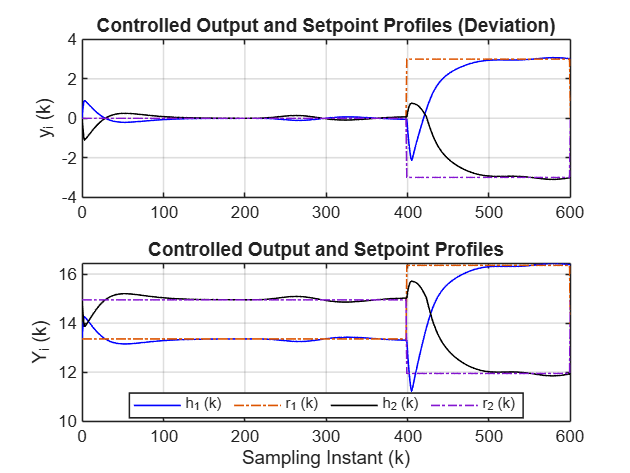

figure, subplot(211), 
plot(kT, yk(1,:), 'b',  kT, r_k(1,:), '-.', kT, yk(2,:), 'k', kT, r_k(2,:), '-.'), grid
title('Controlled Output and Setpoint Profiles (Deviation)'), ylabel('y_i (k)')
subplot(212), plot(kT, Yk(1,:), 'b',  kT, R_k(1,:), '-.', kT, Yk(2,:), 'k', kT, R_k(2,:), '-.'), grid
xlabel('Sampling Instant (k)'), ylabel('Y_i (k)')
legend('h_1 (k)', 'r_1 (k)', 'h_2 (k)', 'r_2 (k)', 'Orientation','horizontal','Location','Best')
title('Controlled Output and Setpoint Profiles')

**Manipulated input profiles**

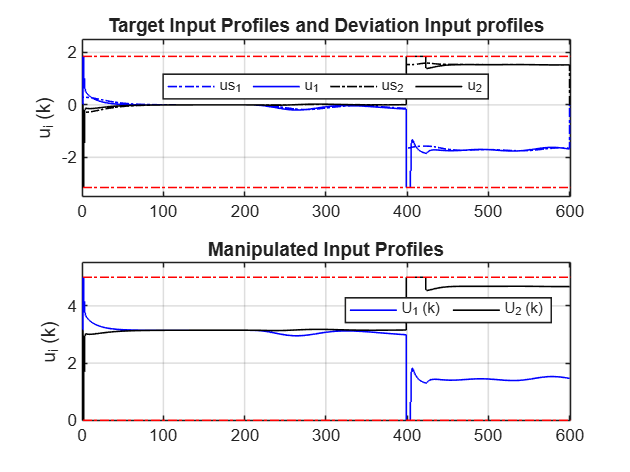

figure, subplot(211), stairs(kT, us_k(1,:)', '-.b','LineWidth',1), grid
hold on
stairs(kT, uk(1,:)', 'b','LineWidth',1)
stairs(kT, us_k(2,:)', '-.k','LineWidth',1)
stairs(kT, uk(2,:)', 'k','LineWidth',1)
stairs(u_limit, '-.r', 'LineWidth',1)
axis([0 N -3.5 2.5])
hold off
ylabel('u_i (k)'), title('Target Input Profiles and Deviation Input profiles')
legend( 'us_1', 'u_1', 'us_2', 'u_2', 'Orientation','horizontal','Location','Best')
subplot(212), stairs(kT, Uk(1,:)', 'b','LineWidth',1),  grid
hold on, stairs(kT, Uk(2,:)', 'k','LineWidth',1),
stairs(u_limit+QTank.Us', '-.r', 'LineWidth',1), hold off
axis([0 N 0 5.5]), ylabel('u_i (k)')
title('Manipulated Input Profiles')
legend( 'U_1 (k)', 'U_2 (k)','Orientation','horizontal','Location','Best')

** Disturbance input and Model Plant Mismatch profiles **

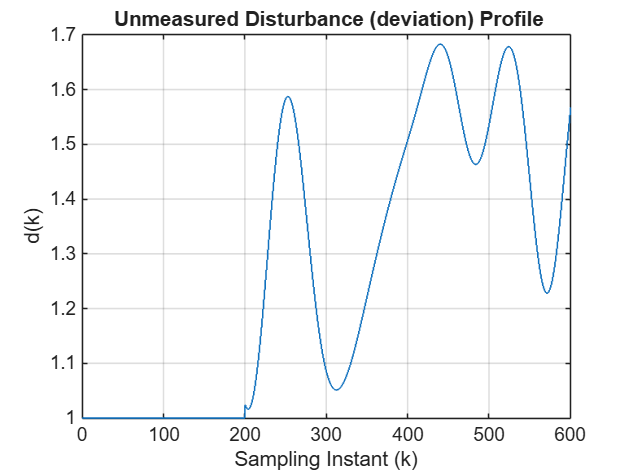

figure,  stairs( kT, Dk,'LineWidth',1 ), grid
xlabel('Sampling Instant (k)'), ylabel('d(k)')
title(' Unmeasured Disturbance (deviation) Profile')

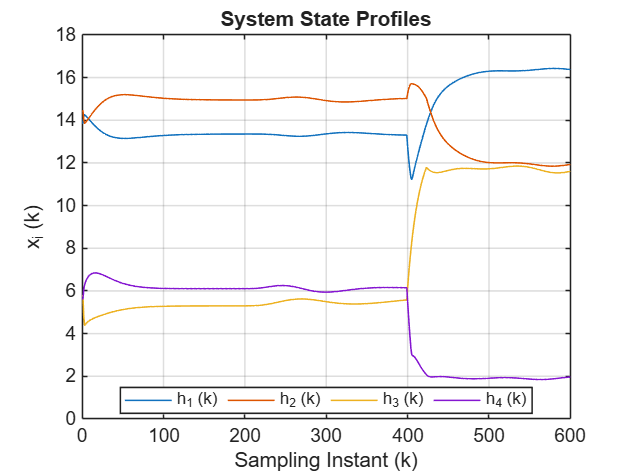


% System State profiles and MPC internal model profiles  
figure, plot(kT, Xk(1,:), kT, Xk(2,:), kT, Xk(3,:), kT, Xk(4,:)), grid
xlabel('Sampling Instant (k)'), ylabel('x_i (k)')
legend('h_1 (k)', 'h_2 (k)', 'h_3 (k)', 'h_4 (k)', 'Orientation','horizontal','Location','Best')
title('System State Profiles')

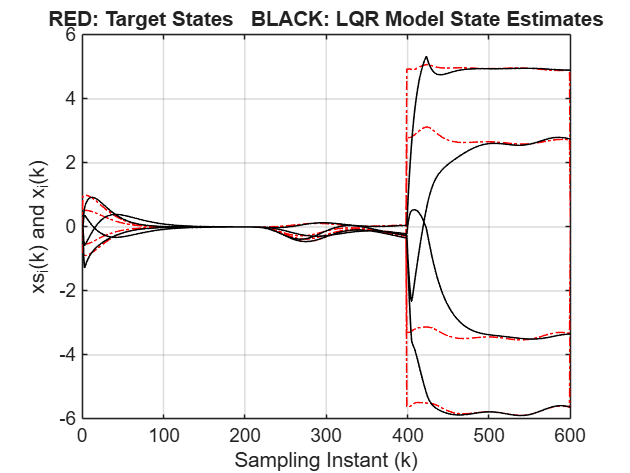

figure, plot(kT, xs_k, '-.r', kT, xkhat, 'k'), grid
title('RED: Target States   BLACK: LQR Model State Estimates')
xlabel('Sampling Instant (k)'), ylabel('xs_i(k) and x_i(k)')

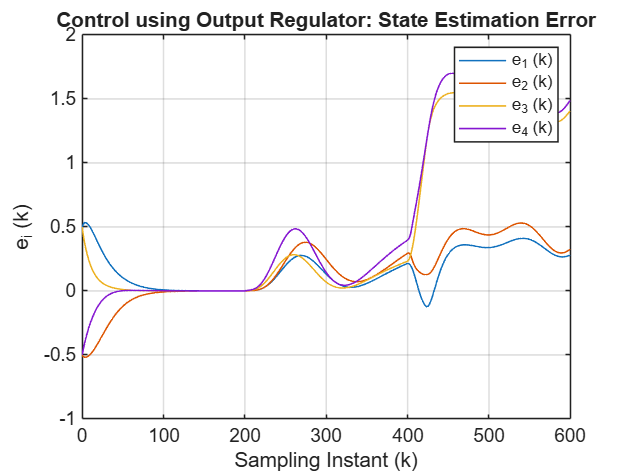

figure, plot(kT, est_err(1,:), kT, est_err(2,:), kT, est_err(3,:), kT, est_err(4,:)), grid
 xlabel('Sampling Instant (k)'), ylabel('e_i (k)')
 legend('e_1 (k)', 'e_2 (k)', 'e_3 (k)', 'e_4 (k)'), title('Control using Output Regulator: State Estimation Error')

## Innovation Filter

When the measurements are corrupted with zero mean random noise and disturbance input is also corrupted with zero mean noise, the innovation signal has significant high frequency component, which can result in undesirable oscillations in the manipulated inputs. The low frequency drifting mean of $\left\lbrace e\left(k\right)\right\rbrace$can be estimated using a simple unity gain first order filter of the form

$\begin{array}{l}
e_f \left(k\right)=\Phi_e e_f \left(k-1\right)+\left(I-\Phi_e \right)e\left(k\right)\\
\Phi_e =\textrm{diag}\left\lbrack \begin{array}{cccc}
\alpha_1  & \alpha_2  & \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp  & \alpha_1 
\end{array}\right\rbrack 
\end{array}$  ------(33)

where  $0\le \alpha_i \le 1\;\;\;\;\;i=1,2\ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp r$ are the tuning parameters.  Choice of this parameter influences the regulatory (disturbance rejection) behavior of the LQG controller. Similarly, the setpoint changes can be introduced by filtering through low pass unity gain filter to avoid sudden changes in the manipulated inputs. 

$\begin{array}{l}
r_f \left(k+1\right)=\Phi_r r_f \left(k\right)+\left(I-\Phi_r \right)r\left(k\right)\\
\Phi_e =\textrm{diag}\left\lbrack \begin{array}{cccc}
\beta_1  & \beta_2  & \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp  & \beta_r 
\end{array}\right\rbrack 
\end{array}$  ------(34)

where  $0\le \beta_i \le 1\;\;\;\;\;i=1,2\ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp r$ are the tuning parameters. Here we demonstrate the effect of innovation filtering on the closed loop behavior. The target state and input calculations are modified using these filtered signals as follows: 

When $l=m$, we can derive expression for $u_s \left(k\right)$ as follows 

 $u_s \left(k\right)={\left(G\right)}^{-1} \;\left(r_f \left(k\right)-G_e \;e_f \left(k\right)\right)$------(35)

When $u_s \left(k\right)$ computed using (27) is outside the input bounds, or when $l\not= m$, the target state can be computed by solving $u_s \left(k\right)$ can be found by solving the following optimization problem

$\min_{u_s \left(k\right)} \left\lbrace {\left(r_f \left(k\right)-y_s \left(k\right)\right)}^T \;W_{\textrm{ys}} \left(r_f \left(k\right)-y_s \left(k\right)\right)\right\rbrace$   ------(36)

subject to,

$y_s \left(k\right)=G\;u_s \left(k\right)+G_e \;e_f \left(k\right)$ ------(37) 

$u^L \le u_s \left(k\right)\le u^H$ ------ (38)

After solving the optimization problem the target state, $x_s \left(k\right)$, can be found using equation 

$x_s \left(k\right)={\left(I-\Phi \right)}^{-1} \left(\Gamma u_s \left(k\right)+L{\mathrm{e}}_f \left(k\right)\right)$   ------(39)

### **Q-Tank Control Using Output Regulator with Innovation Filter**

We now add the innovation filter and observe the closed loop behaviour of the controller.

global QTank U_k D_k
 N = 651 ; 
xk = zeros(n_st,N);
xs_k = zeros(n_st,N);
yk = zeros(n_op,N) ;
est_err = zeros(n_st,N); 
xkhat = zeros(n_st,N);
xk(:,1) = [1 -1 1 -1]';
uk = zeros(n_ip,N) ;
us_k = zeros(n_ip,N) ;
dk = zeros(1,N) ;
ek = zeros(n_op,N) ;
ek_f = zeros(n_op,N) ;

**Task 6:** To run the closed loop simulations with Innovation Filter Set innovation_filter_on to 1

innovation_filter_on = 0 ;

**Innovation filter parameters**

**Task 7: **Set alfa_d value to 0 to see effect of noise on u(k). Values close to 1 will mitigate the fluctuations caused by noise. 

alfa_d =0.9;  % Set this value to 0 to see effect of noise on u(k) 
phy_d = alfa_d * eye(n_op) ;  % Innovation filter 
rk_f = zeros(n_op,N);     % Setpoint filter parameters 

**Setpoint filter parameters **

**Task 8:** Users can Set this value to 0 see effect of step change in rk on u(k). It can be observed that the inputs suddenly rise, when step change is given.

beta_r=0.85;
  % Set this value to 0 see effect of step change in rk on u(k)
phy_r = beta_r * eye(n_op) ; % 

 Generate state and measurement noise sequences 

**Task 9:** Set the value of Noise_ON to 1 to introduce white noise disturbances  

Noise_ON=1% Set this value to 1 to introduce white noise disturbances  

Noise_ON = 1

wk = mvnrnd(zeros(n_d,1), Q_mat, N) ;
wk = Noise_ON * wk' ;
vk = mvnrnd(zeros(n_op,1), R_mat, N) ;
vk = Noise_ON * vk' ;

** Disturbance input **

A time varying disturbance input signal is generated such that initially it is set to zero for $k<0$. It is changed such that $200\le k<400$ it 's magnitude is 0.5 and for $k>400$ it is 0.25

for k = 1:N
    if ( k < 200 )
        dk(k) = 0 ;
    elseif (k >= 200 ) && (k < 400)
        dk(k) = 0.5 ;  % Introduce disturbance change at k = 200
    else
        dk(k) = 0.25  ;  % Introduce another disturbance change at k = 400
    end
end

dk = dk + [zeros(1, 200) wk(201:end) ] ; 

rk = zeros(n_op,1) ;

**Task 10: **Select Plant_Sim as Nonlinear for simulating Q Tank process using a nonlinear ODE model. Selecting Linear simulated plant dynamics using linear difference equation model.  

Plant_Sim =0  ;

for k = 1:N-1
    kT(k) = (k-1);

     ek(:,k) = yk(:,k) - C_mat * xkhat(:,k) ;  
     ek_f(:,k+1) = phy_d * ek_f(:,k) + (eye(n_op) - phy_d) * ek(:,k) ; 

     % Setpoint change introduced simultaneously with the disturbance
     % change at k = 400
     if (k >= 400),   rk = [ 3 -3 ]';  end  
     rk_f(:,k+1) = phy_r * rk_f(:,k) + (eye(n_op) - phy_r) * rk   ; 

     % Control law calculations at sampling instant k 
     if (innovation_filter_on )
         us_k(:,k) = inv(Gain_ss) * ( rk_f(:,k+1) - Gain_e * ek_f(:,k))  ;
         xs_k(:,k) = inv(eye(n_st) - phy) * ( gam * us_k(:,k) + L_inf * ek_f(:,k))  ;
     else
         us_k(:,k) = inv(Gain_ss) * ( rk_f(:,k+1)- Gain_e * ek(:,k))  ;
         xs_k(:,k) = inv(eye(n_st) - phy) * ( gam * us_k(:,k) + L_inf * ek(:,k))  ;
     end

    uk_uncon = us_k(:,k) - G_inf * (xkhat(:,k) - xs_k(:,k)) ;
    uk_clipped = uk_bound_constraints( uk_uncon, u_L, u_H ) ;
    uk(:,k) = uk_clipped ; 

    % Update state estimator from instant k to k+1 using uk
    xkhat(:,k+1) = phy * xkhat(:,k) + gam * uk(:,k) + L_inf * ek(:,k) ;
    est_err(:,k) = xk(:,k) - xkhat(:,k) ;

     % Quadruple tank Plant Simulation from k to k+1
    if (Plant_Sim )
        xk(:,k+1) = phy * xk(:,k) + gam * uk(:,k) + gam_d * dk(k)  ;
    else
        U_k = QTank.Us +uk(:,k) ;  
        D_k = QTank.Ds + dk(k)  ;
        [T,Xt] = ode45( 'QTank_Dynamics' , [ 0 QTank.samp_T ], QTank.Xs+xk(:,k)) ;   % Nonlinear plant simulation
        xk(:,k+1) = Xt( end,: )' - QTank.Xs ;
    end
    yk(:,k+1) = C_mat * xk(:,k+1) + vk(:,k+1);  %Measurement with noise 

 end
uk(:,N) = uk(:,N-1) ;
est_err(:,N) =  est_err(:,N-1) ;
ek(:,N) = ek(:,N-1) ;
kT(N) = N-1 ; 

**Simulation Results**

Xk = QTank.Xs + xk ;   Uk = QTank.Us + uk ; Dk = QTank.Ds + dk ;
Yk = yk + C_mat * QTank.Xs ;  Rk_f = rk_f + C_mat * QTank.Xs ;
u_limit = [u_L(1)*ones(N,1) u_H(1)*ones(N,1)]  ;

**Controlled output profiles **

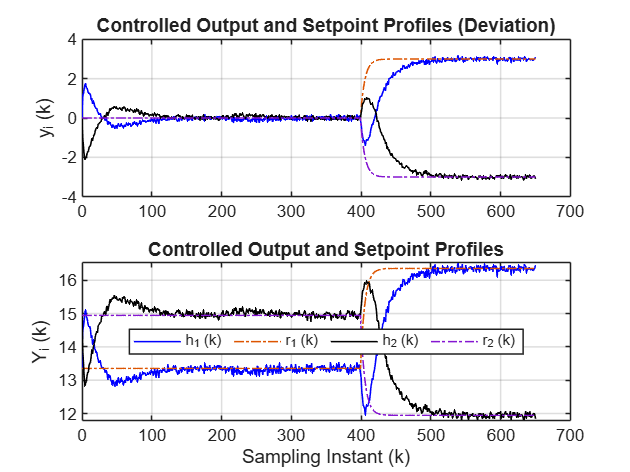

figure, subplot(211), 
plot(kT, yk(1,:), 'b',  kT, rk_f(1,:), '-.', kT, yk(2,:), 'k', kT, rk_f(2,:), '-.'), grid
title('Controlled Output and Setpoint Profiles (Deviation)'), ylabel('y_i (k)')
subplot(212), plot(kT, Yk(1,:), 'b',  kT, Rk_f(1,:), '-.', kT, Yk(2,:), 'k', kT, Rk_f(2,:), '-.'), grid
xlabel('Sampling Instant (k)'), ylabel('Y_i (k)')
legend('h_1 (k)', 'r_1 (k)', 'h_2 (k)', 'r_2 (k)', 'Orientation','horizontal','Location','Best')
title('Controlled Output and Setpoint Profiles')

**Manipulated input profiles**

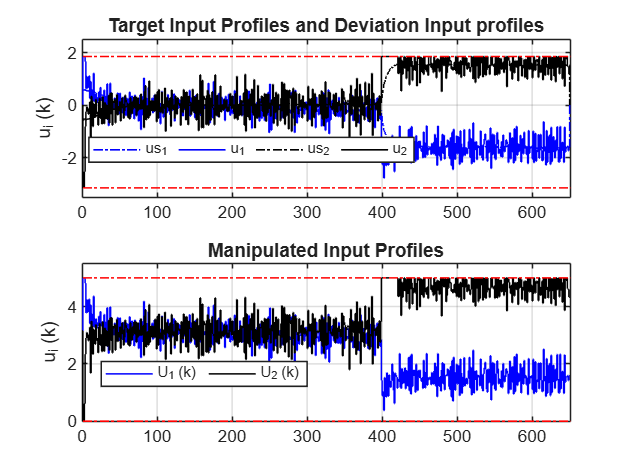

figure, subplot(211), stairs(kT, us_k(1,:)', '-.b','LineWidth',1), grid
hold on
stairs(kT, uk(1,:)', 'b','LineWidth',1)
stairs(kT, us_k(2,:)', '-.k','LineWidth',1)
stairs(kT, uk(2,:)', 'k','LineWidth',1)
stairs(u_limit, '-.r', 'LineWidth',1)
axis([0 N -3.5 2.5])
hold off
ylabel('u_i (k)'), title('Target Input Profiles and Deviation Input profiles')
legend( 'us_1', 'u_1', 'us_2', 'u_2', 'Orientation','horizontal','Location','Best')
subplot(212), stairs(kT, Uk(1,:)', 'b','LineWidth',1),  grid
hold on, stairs(kT, Uk(2,:)', 'k','LineWidth',1),
stairs(u_limit+QTank.Us', '-.r', 'LineWidth',1), hold off
axis([0 N 0 5.5]), ylabel('u_i (k)')
title('Manipulated Input Profiles')
legend( 'U_1 (k)', 'U_2 (k)','Orientation','horizontal','Location','Best')

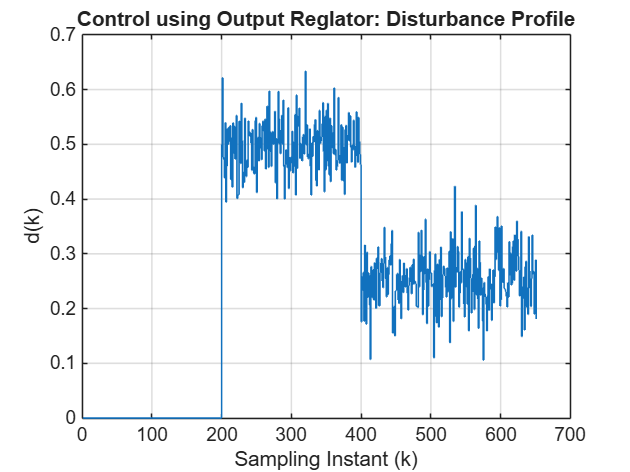

figure, stairs(dk, 'LineWidth',1), grid
xlabel('Sampling Instant (k)'), ylabel('d(k)'), title('Control using Output Reglator: Disturbance Profile')

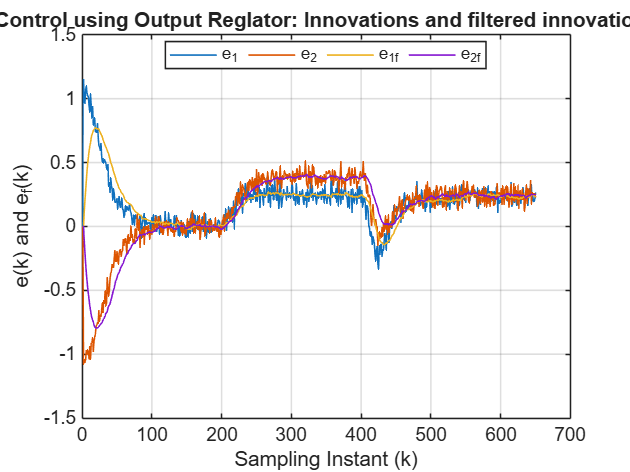

figure, plot(ek', 'LineWidth',1), grid
hold on 
plot(ek_f', 'LineWidth',1)
hold off 
xlabel('Sampling Instant (k)'), ylabel('e(k) and e_f(k)')
legend('e_1', 'e_2', 'e_1_f', 'e_2_f', 'Orientation','horizontal','Location','Best')
title('Control using Output Reglator: Innovations and filtered innovations')

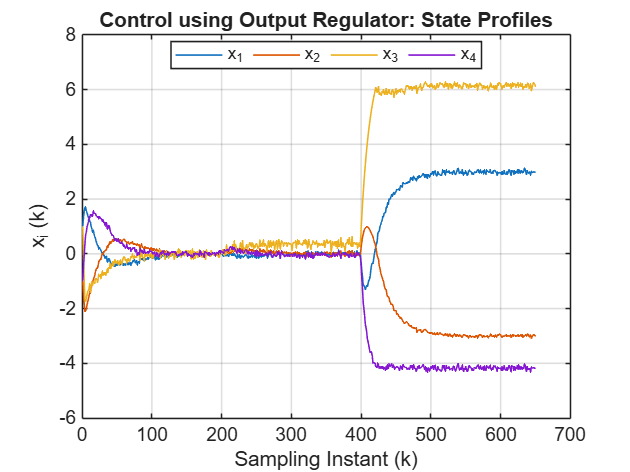

figure(20), plot(kT, xk(1,:), kT, xk(2,:), kT, xk(3,:), kT, xk(4,:)), grid
xlabel('Sampling Instant (k)'), ylabel('x_i (k)')
legend('x_1', 'x_2', 'x_3', 'x_4' , 'Orientation','horizontal','Location','Best'), 
title('Control using Output Regulator: State Profiles')

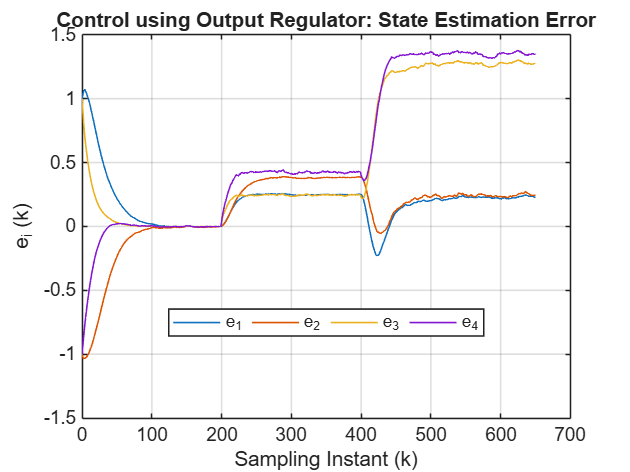

figure(21), plot(kT, est_err(1,:), kT, est_err(2,:), kT, est_err(3,:), kT, est_err(4,:)), grid
xlabel('Sampling Instant (k)'), ylabel('e_i (k)')
legend('e_1', 'e_2', 'e_3', 'e_4', 'Orientation','horizontal','Location','Best'), 
title('Control using Output Regulator: State Estimation Error')

**Task 11: **Now set alfa_d to maximum value and observe the input profiles. 

**Task 12: **Now run the simulation without innovation filter. Note the changes in the input profiles.

**Task 13:** Now you can make the noise zero and observe the outputs. Again turn on the innovation filter.

**Task 14: **Users can change the operating point and repeat the exercise

As evident from this simulation exercise, fluctuations in the manipulated inputs reduce significantly when innovation signal is filtered using a unity gain filter. The last figure shows that the innovation signal reduces to a zero mean white noise signal (between instant 100 to 200) where there is no unmeasured disturbance or MPM. However, the innovation signal becomes biased (non-zero mean) when the drifting unmeasured disturbance is introduced (for k > 200) or PMM is additionally introduced when plant dynamics are simulated using nonlinear ODEs. The filtered innovation captures the drifting mean of the innovations, which needs to be dealt with for achieving offset fee control through computation of target states an target inputs.  

## Conclusions 

In this lesson, we have seen that the LQOC can be used for simultaneous set point tracking and disturbance rejection. Further when the measurements and disturbance signals are corrupted with noise, the resulting fluctuations in the manipulated inputs can be reduced significantly using a unity gain filter to filter the innovation signal from the state estimator. The input constraints, however, are handled in an ad-hoc manner. In the next lesson, we use a stationary Kalman filter to implement an MPC-QP formulation, which can handle input constraints in a systematic manner.  